clear;

i = [0.5, 6.0, 10.5];
D = [16, 32, 48];
Y_r = 10E6;

P = zeros(3,3);
y = zeros(3,3);

p = (1 + i./100).^(1/12);

% Figure out monthly payments
C = (Y_r .* (p - 1)) ./ (p .* (p.^(12.*D') - 1)) % D x i

C =    1.0e+04 *

    5.0022    3.1447    2.1026
    2.4014    0.8883    0.3539
    1.5363    0.3147    0.0693


P = 12.*D'.*C

P =    1.0e+06 *

    9.6043    6.0379    4.0370
    9.2213    3.4109    1.3591
    8.8489    1.8125    0.3990


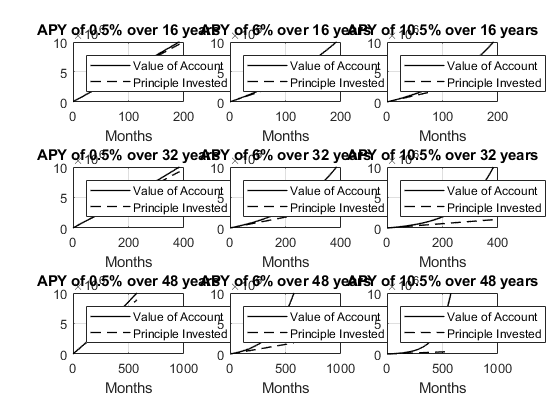

% for j = 1:1:3
%     for k = 1:1:3 
%         % Check that the monthly payments make sense recursively
%         y_t = zeros(12*D(k)+1,1);
%         for l = 0:1:(12*D(k)-1)
%             y(j,k) = (1+i(j)/12) * y(j,k) + C(j,k);
%             y_t(l+1) = y(j,k);
%         end
%         y(j,k) = (1+i(j)/12) * y(j,k);
%         y_t(12*D(k)+1) = y(j,k);   
%     end
% end

        
u = @(t) 1.0 .* (t >= 0);
y = @(n, C, p, D) C ./ (p - 1) .* ( (p.^(n + 1) - 1).*u(n) - (p.^(n + 1 - 12*D) - 1).*u(n - 12*D));
for j = 1:1:3
    n = 0:1:(D(j)*12);
    P_t = (n+1) .* C(j,:)';
    y_t = y(n, C(j,:)', p', D(j));
    for k = 1:1:3     
        % Plot the value of the retirement account as a function of month over the investment interval.
        subplot(3,3,((j-1)*3+k-1)+1);
        plot(n, y_t(k,:), '-', n, P_t(k,:), '--', 'color', [0,0,0], 'linewidth', 1);
        %ylim([0 10E6]);
        xlabel('Months');
        %ylabel("Value of Account");
        title("APY of " + string(i(k))+"% over " + string(D(j)) + " years");
        grid on;
        legend('Value of Account', 'Principle Invested', 'Location','northwest');
    end
end

C

C =    1.0e+04 *

    5.0022    3.1447    2.1026
    2.4014    0.8883    0.3539
    1.5363    0.3147    0.0693


C_s = strings(3);
for i=1:3
    for j=1:3
        C_s(i,j) = num2bank(C(i,j));
    end
end
C_s

C_s = 3×3 string array
    "50,022.43"    "31,447.18"    "21,026.04"
    "24,013.78"    "8,882.5"      "3,539.26" 
    "15,362.61"    "3,146.68"     "692.73"   


y;
P;
P_s = strings(3);
for i=1:3
    for j=1:3
        P_s(i,j) = "$" + num2bank(P(i,j));
    end
end
P_s

P_s = 3×3 string array
    "$9,604,306.85"    "$6,037,859.32"    "$4,037,001.33"
    "$9,221,295.05"    "$3,410,881.1"     "$1,359,078.81"
    "$8,848,866.52"    "$1,812,492.71"    "$399,015.65"  
